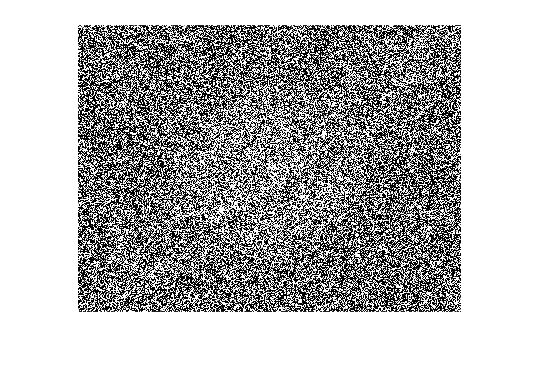

load('Important_files/noisy.mat');
imshow(noisy);

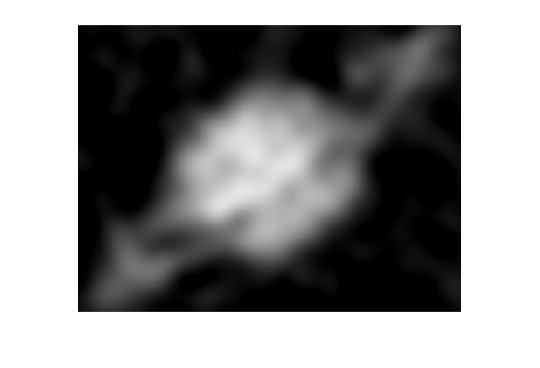

kernel_size = 78;
sigma = kernel_size/6;
g = fspecial('gaussian', kernel_size, sigma);
filtim = filter2(g, noisy);
imshow(filtim)

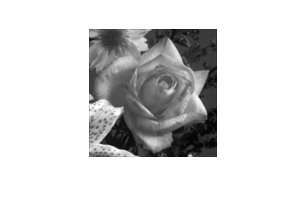

flower = double(imread('Important_files/flower.tif'));
imshow(flower,[]);

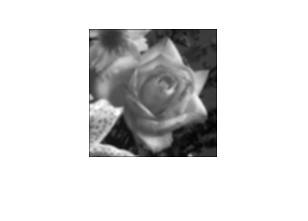


g_avg = fspecial('average' ,3);
img_avg = filter2(g_avg,flower);
imshow(img_avg,[]);

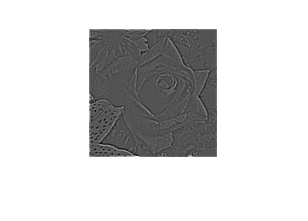


hipass_img = flower - img_avg;
imshow(hipass_img,[]);


avg = mean(mean(hipass_img));

avg = 0.9114

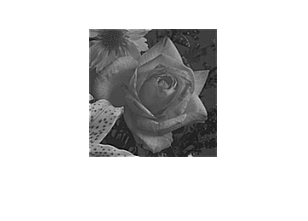

A = 2;
detailed_flower = flower + A * hipass_img;
imshow(detailed_flower,[]);

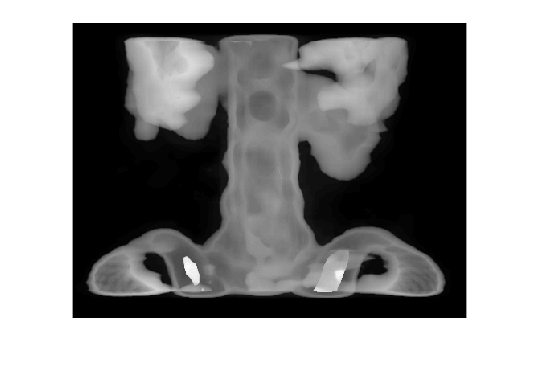

load('Important_files/spine4.mat');
imshow(spine4, []);

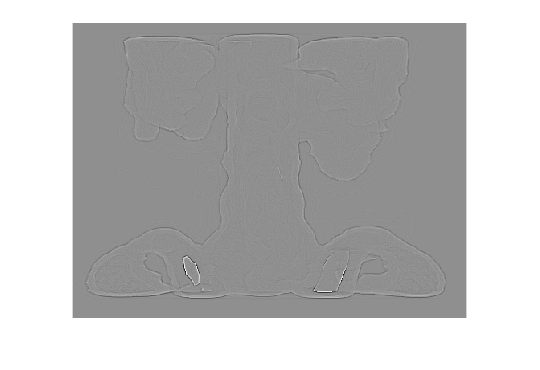

hp = (1./9).*[-1 -1 -1; 
              -1 8 -1; 
              -1 -1 -1];
hpspine = filter2(hp,spine4);
imshow(hpspine, []);

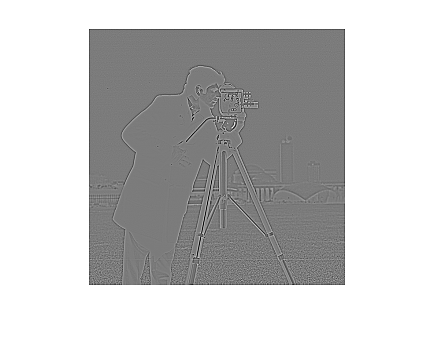

cam = imread('Important_files/cameraman.tif');

g_lap = fspecial('laplacian');
cam_lap = filter2(g_lap,cam);
imshow(cam_lap,[])


g_us = fspecial('unsharp');
cam_us = filter2(g_us,cam);
imshow(double(cam)-double(cam_us),[])

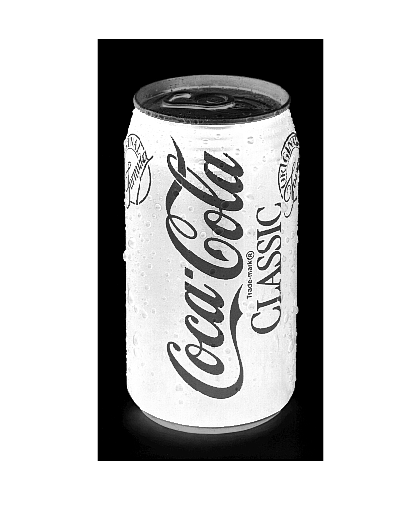

load('Important_files/coke2.mat');
imshow(coke,[])

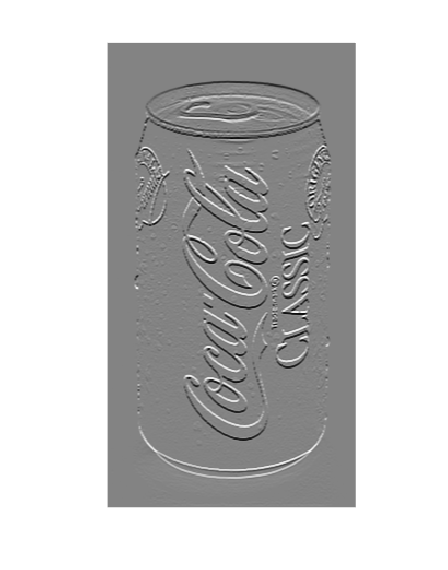

sbh=[1 2 1; 0 0 0; -1 -2 -1];
sbv=[1 0 -1; 2 0 -2; 1 0 -1];

cokeh= filter2(sbh,coke); 
cokev= filter2(sbv,coke);

imshow(cokeh,[]);

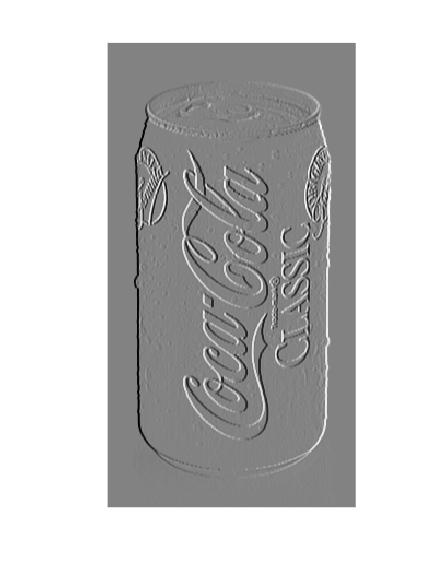

imshow(cokev,[]);

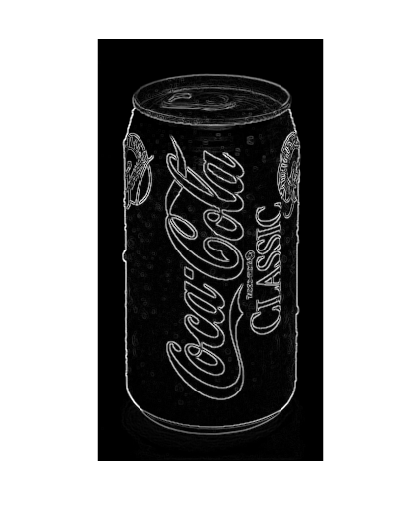


cokea=abs(cokeh) + abs(cokev);
coken = cokea./max(max(cokea));

imshow(coken,[])

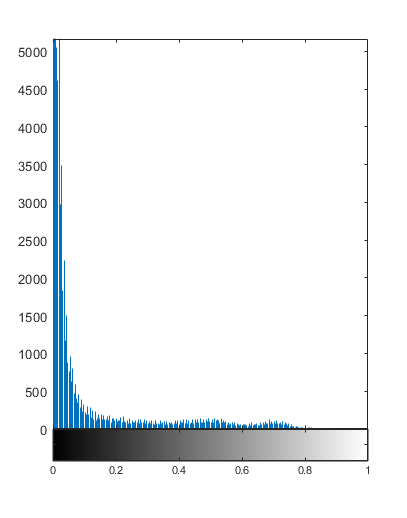

imhist(coken)

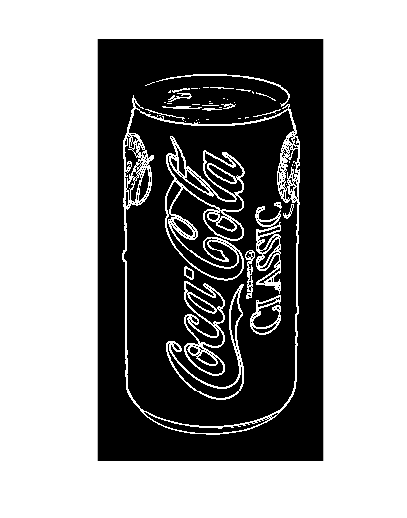


cokebw = im2bw(coken, 0.26);
imshow(cokebw,[])